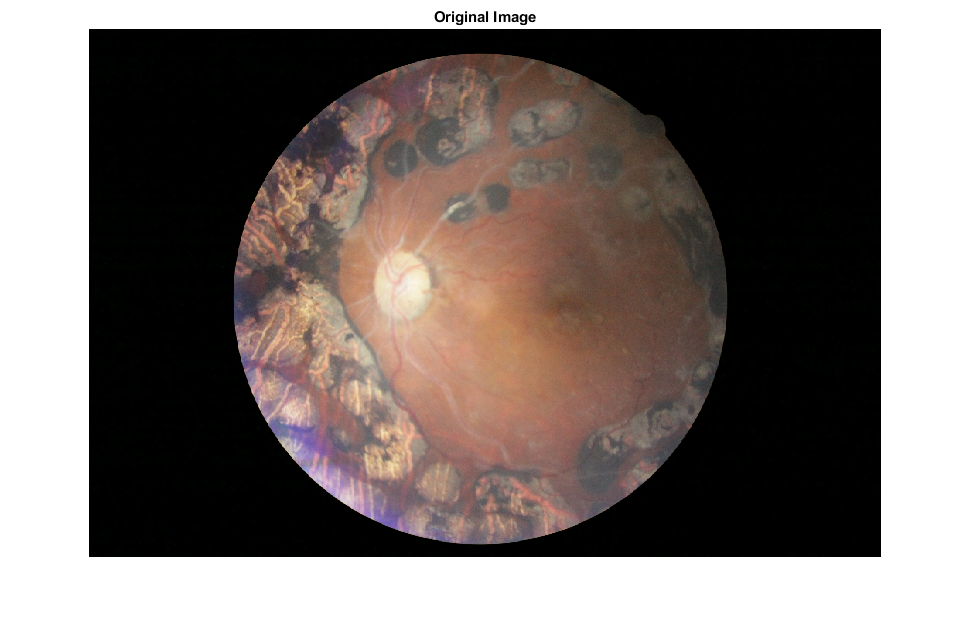

clc; clear ; close all

 
% path = 'M:\Desktop\compapp\MASK Project\Mask\batch1\';
% files = dir(strcat(path,'\\*.jpeg'));
% RGB = imread(strcat(path,files(ii).name))
RGB = imread('16309_left(n).jpeg');

figure

imshow(RGB)

title('Original Image')

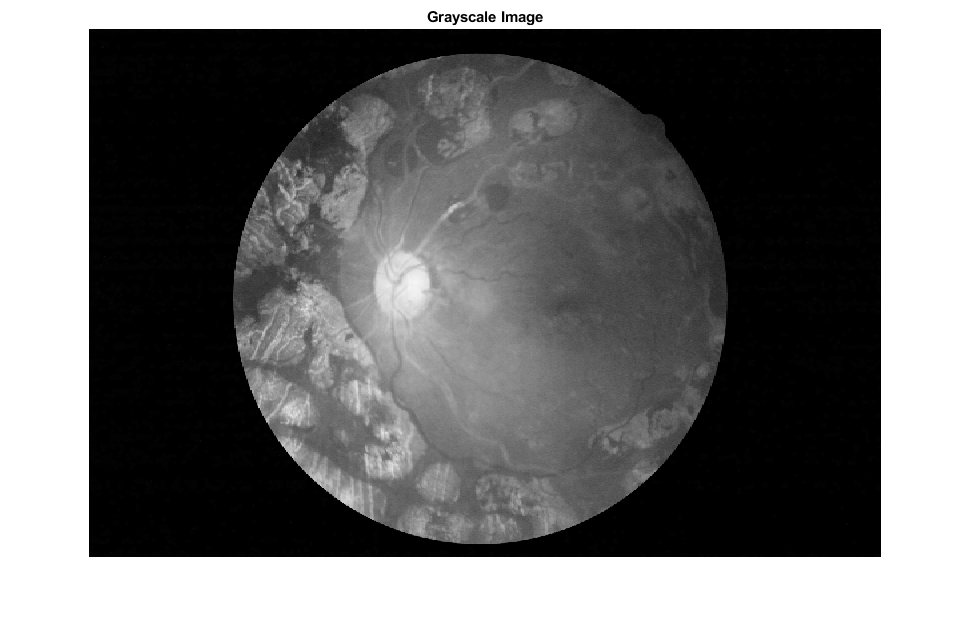


 

% extract only green channel

I = RGB(:,:,2);

figure

imshow(I)

title('Grayscale Image')

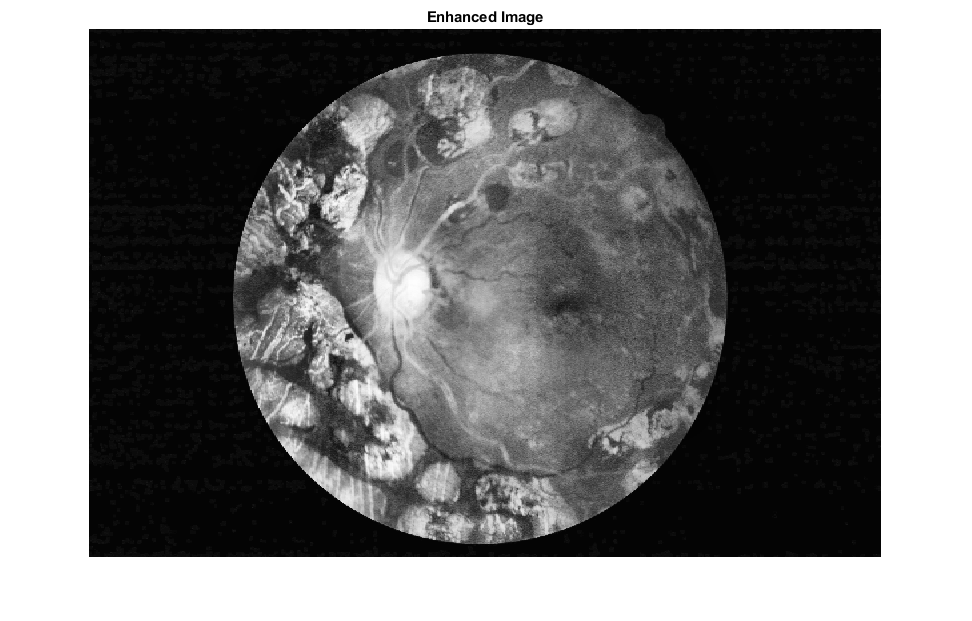


 

J = adapthisteq(I);

figure

imshow(J)

title('Enhanced Image')

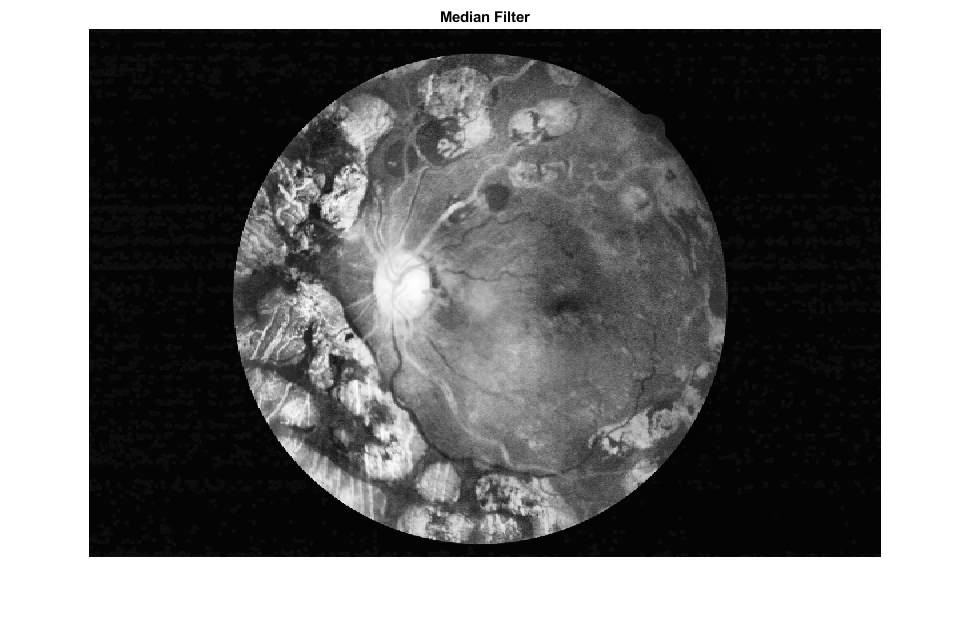


 

neighborhoodSize = [3 3];

K = medfilt2(J,neighborhoodSize);

figure

imshow(K);

title('Median Filter')

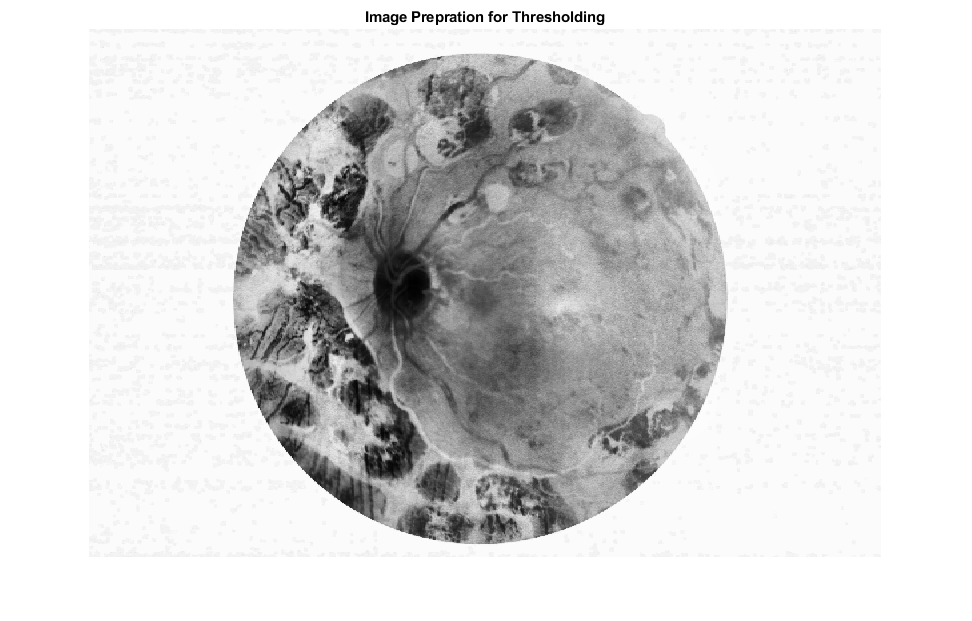


 

windowWidth = 3;

kernel = ones(windowWidth) / windowWidth ^2;

Kc = conv2(K, kernel,'same');

B = (uint8(Kc)*255) - K;

figure

imshow(B);

title('Image Prepration for Thresholding')

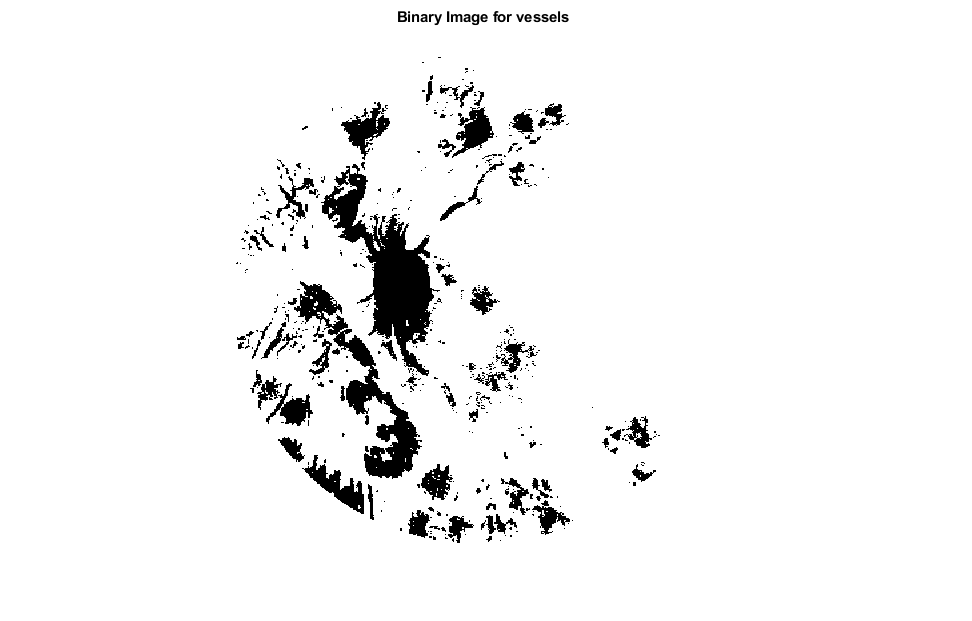


 
%This is the segmentation result and the part we will use for
%classification
BW1 = B > 85;

figure

imshow(BW1);

title('Binary Image for vessels ')


 

% BW2 = imcomplement(J > 28);
% 
% figure
% 
% imshow(BW2);
% 
% title('Binary Image for Background')

 

% BW = xor(BW1,BW2);
% 
% figure
% 
% imshow(BW);
% 
% title('Binary Image')

 
% 
% % obtained the segmented image
% 
% maskedImage = J;
% 
% maskedImage(~BW) = 0;

 
% 
% % visualize the segmented image
% 
% figure
% 
% imshow(maskedImage)
% 
% title('Masked Image')

 

%Classification

blackPixels = numel(BW1)-sum(BW1(:));

count_0 = 0;

count_1 = 0;

count_2 = 0;

count_3 = 0;

count_4 = 0;

if blackPixels < 300000

    fprintf('The severity is 0 on 0-4 scale');

    count_0 = count_0 + 1;

elseif blackPixels >= 300000 && blackPixels < 500000

    fprintf('The severity is 1 on 0-4 scale');

    count_1 = count_1 + 1;

elseif blackPixels >= 500000 && blackPixels < 700000

    fprintf('The severity is 2 on 0-4 scale');

    count_2 = count_2 + 1;

elseif blackPixels >= 700000 && blackPixels < 1000000

    fprintf('The severity is 3 on 0-4 scale');

    count_3 = count_3 + 1;

else

    fprintf('The severity is 4 on 0-4 scale');

    count_4 = count_4 + 1;

end

The severity is 4 on 0-4 scale